## Exercício 6

    Neste exercício, vamos modelar o comportamento de um *link* de comunicações IP que possui uma fila de espera finita. Na Teoria de Filas de Espera, isto traduz-se no modelo **M/M/1/m**.

    Temos de ter em atenção um detalhe conceptual crucial: a capacidade do sistema ($m$) não é igual ao tamanho da fila de espera ($Q$). O sistema acomoda os pacotes que estão na fila mais o pacote que está a ser processado (transmitido) pelo servidor (neste caso, o *link* IP). Logo, $m=Q+1$.

Antes de aplicar as probabilidades, temos de converter as taxas (que estão em Mbps) para pacotes por segundo (pps):

- **Taxa de Serviço (**$\mu$**):** É a capacidade do *link* a dividir pelo tamanho do pacote. Como 1 Byte tem 8 bits, $\mu =(100\times 10^6 )/(800\times 8)$.

- **Taxa de Chegada (**$\lambda$**):** É o tráfego oferecido a dividir pelo tamanho do pacote. Logo, $\lambda =(80\times 10^6 )/(800\times 8)$.

- **Carga do Sistema (**$\rho$**):** O rácio $\rho =\lambda /\mu$.

    Para a alínea (a), o rácio de pacotes perdidos (*Packet Loss Rate*) é a probabilidade do sistema estar completamente cheio ($P_m$). O atraso médio calcula-se descobrindo primeiro a média de pacotes no sistema ($L$) e aplicando a Lei de Little com a taxa de chegada efetiva ($W=L/\lambda_{eff}$).

Para a alínea (b), o problema inverte-se. Queremos garantir que o *Packet Loss Rate* é $\le 0.1\%$. Não existe uma fórmula direta linear para isolar o $m$, pelo que usamos um método iterativo.

**O Código:**

A primeira parte do código traduz diretamente as fórmulas analíticas do modelo M/M/1/m para $Q=8$.

Na alínea (b), utilizamos um ciclo while. Começamos com $Q=1$ e vamos calculando iterativamente a probabilidade de bloqueio. Enquanto a probabilidade for superior a $0.1\%$, o ciclo incrementa o valor de $Q$ em uma unidade. Quando finalmente desce do patamar imposto, o ciclo quebra e imprime o $Q$ correspondente.

%% Exercício 1 - Link de Comunicações IP (M/M/1/m)
clear all; close all; clc;

% --- 1. Conversão e Parâmetros ---
C = 100e6;       % Capacidade do link (bps)
T = 80e6;        % Throughput de entrada (bps)
B = 800 * 8;     % Tamanho médio do pacote em bits

mu = C / B;      % Taxa de serviço (pacotes/segundo)
lambda = T / B;  % Taxa de chegada (pacotes/segundo)
rho = lambda / mu; % Tráfego oferecido

fprintf('--- Alínea (a) ---\n');

--- Alínea (a) ---


Q = 8;
m = Q + 1;       % Capacidade total do sistema (fila + servidor)

% Cálculo da taxa de perda (Probabilidade do estado m)
Pm = ((1 - rho) / (1 - rho^(m+1))) * rho^m;
PLR = Pm * 100;

% Cálculo do Atraso Médio
% 1. Número médio de pacotes no sistema (L)
L = (rho / (1 - rho)) - ((m + 1) * rho^(m+1)) / (1 - rho^(m+1));
% 2. Taxa de chegada efetiva
lambda_eff = lambda * (1 - Pm);
% 3. Lei de Little (em milissegundos)
W_ms = (L / lambda_eff) * 1000;

fprintf(' Avg. packet delay = %.3f msec.\n', W_ms);

 Avg. packet delay = 0.231 msec.


fprintf(' Packet loss rate = %.3f%%\n\n', PLR);

 Packet loss rate = 3.007%




fprintf('--- Alínea (b) ---\n');

--- Alínea (b) ---


Q_min = 1;       % Valor de teste inicial para a fila
PLR_b = 100;     % Inicialização com perda máxima teórica

% Ciclo iterativo para encontrar a fila mínima necessária
while PLR_b > 0.1
    m_b = Q_min + 1;
    Pm_b = ((1 - rho) / (1 - rho^(m_b+1))) * rho^m_b;
    PLR_b = Pm_b * 100;

    if PLR_b > 0.1
        Q_min = Q_min + 1;
    end
end

fprintf(' Minimum queue size = %d packets\n', Q_min);

 Minimum queue size = 23 packets


fprintf(' Packet loss rate = %.5f%%\n', PLR_b);

 Packet loss rate = 0.09481%


    Através da modelação e observação dos resultados, constatamos o efeito direto do dimensionamento de *buffers* num equipamento de rede. Quando a fila é muito curta ($Q=8$), o atraso é excecionalmente baixo (menos de um quarto de milissegundo) porque os pacotes nunca ficam "engarrafados"; em contrapartida, deitamos fora cerca de 3% de todo o tráfego que chega ao *router*, degradando gravemente a integridade da comunicação.

    Ao aumentarmos a capacidade da fila para $Q=23$, atingimos o limiar de qualidade de serviço (QoS) pretendido, estabilizando as perdas da rede num valor aceitável (abaixo de 0.1%) para absorver com eficácia as flutuações e rajadas estocásticas do tráfego IP de 80 Mbps.

## Exercício 2

    Neste exercício, vamos modelar o comportamento de um servidor de dados que opera em regime de partilha de processamento (*Processor Sharing*). Na Teoria de Filas de Espera, este sistema enquadra-se no modelo **M/M/1/B-PS**, onde não existe propriamente uma "fila" tradicional; todos os pedidos aceites entram imediatamente em processamento e a capacidade da CPU é dividida equitativamente por todos os pedidos ativos até ao limite máximo admissível $B$.

    O ponto central deste problema é descobrirmos a taxa global de serviço do servidor ($\mu$).

    O enunciado diz-nos que, quando o servidor processa a sua capacidade máxima ($B=250$), demora em média $200~\mu s$ a servir cada pedido. Como a capacidade do processador é partilhada de igual forma, o tempo necessário para o servidor despachar 1 único pedido de forma isolada seria de:


$$T_{isolado} =\frac{200~\mu s}{250}=0.8~\mu s$$


A taxa de serviço do servidor ($\mu$) é o inverso do tempo de processamento isolado:


$$\mu =\frac{1}{0.8\times 10^{-6} }=1.25\times 10^6 \;\textrm{pedidos/segundo}$$


Tendo a taxa de chegada ($\lambda =1.23\times 10^6$) e a taxa de serviço ($\mu =1.25\times 10^6$), calculamos a carga do sistema ($\rho =\lambda /\mu =0.984$).

A partir daqui, aplicamos as fórmulas de estado estacionário:

- **Probabilidade de Bloqueio (**$PB$**):** É a probabilidade do sistema estar no estado $B$ (totalmente cheio), ditada por:$PB=\frac{(1-\rho )\rho^B }{1-\rho^{B+1} }$

- **Tempo Médio de Serviço (**$W$**):** No modelo de *Processor Sharing*, o tempo que o cliente passa no sistema é, na verdade, o seu tempo de serviço dilatado pela partilha. Para o calcularmos, primeiro achamos a média de clientes no sistema ($L$) através da série da distribuição, e aplicamos a Lei de Little adaptada para os clientes que efetivamente entram no sistema: $W=L/[\lambda \times (1-PB)]$.

**O Código:**

No script de MATLAB, aplicamos exatamente esta lógica matemática para calcularmos a alínea (a).

Para a alínea (b), geramos um vetor B_vetor com as várias capacidades de limite testadas (200, 250, 300, 350, 400). Usamos um ciclo for para iterar sobre estas capacidades e recalcular tanto o $PB$ como o $W$ para cada uma delas, guardando os resultados em vetores dedicados. Por fim, usamos a função subplot emparelhada com a função bar para gerar os dois gráficos de barras lado a lado exigidos pelo exercício.

%% Exercício 2 - Servidor de Dados (M/M/1/B-PS)
clear all; close all; clc;

% --- 1. Parâmetros Iniciais ---
lambda = 1.23e6;            % Taxa de chegada (pedidos/segundo)
B_ref = 250;                % Capacidade de referência do enunciado
W_ref = 200e-6;             % Tempo médio com 250 pedidos (segundos)

% --- 2. Determinar a taxa de serviço global (mu) ---
% Se 250 pedidos demoram 200 us em simultâneo (dividindo a CPU),
% a taxa total de despachos da máquina é:
mu = B_ref / W_ref;         % 1.25e6 pedidos/segundo
rho = lambda / mu;          % Intensidade de Tráfego (0.984)

fprintf('--- Alínea (a) ---\n');

--- Alínea (a) ---


B = 250;

% Probabilidade de Bloqueio (PB)
PB_a = ((1 - rho) / (1 - rho^(B + 1))) * rho^B;

% Número médio de pedidos a serem processados simultaneamente (L)
L_a = (rho / (1 - rho)) - ((B + 1) * rho^(B + 1)) / (1 - rho^(B + 1));

% Taxa de chegada efetiva (apenas os pedidos que entram)
lambda_eff_a = lambda * (1 - PB_a);

% Tempo médio de serviço dilatado (Lei de Little)
W_a = L_a / lambda_eff_a;

fprintf(' Service blocking probability = %.5f%%\n', PB_a * 100);

 Service blocking probability = 0.02888%


fprintf(' Avg. service time per request = %.3f microseconds\n\n', W_a * 1e6);

 Avg. service time per request = 46.389 microseconds




fprintf('--- Alínea (b) ---\n');

--- Alínea (b) ---


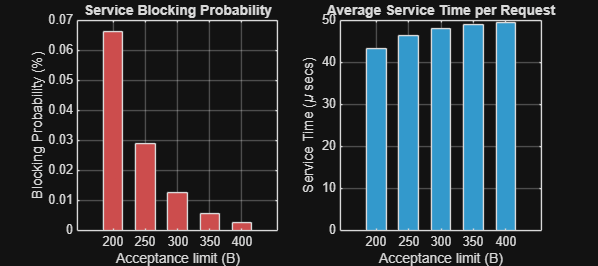

B_vetor = [200, 250, 300, 350, 400];
PB_vetor = zeros(1, length(B_vetor));
W_vetor = zeros(1, length(B_vetor));

% Ciclo para calcular o desempenho com limites diferentes
for i = 1:length(B_vetor)
    b = B_vetor(i);

    % Recalcular PB
    pb = ((1 - rho) / (1 - rho^(b + 1))) * rho^b;
    PB_vetor(i) = pb * 100; % Guardar em percentagem

    % Recalcular L e W
    L_b = (rho / (1 - rho)) - ((b + 1) * rho^(b + 1)) / (1 - rho^(b + 1));
    lambda_eff_b = lambda * (1 - pb);

    W_vetor(i) = (L_b / lambda_eff_b) * 1e6; % Guardar em microssegundos
end

% --- 3. Geração dos Gráficos ---
figure('Name', 'Desempenho do Servidor vs Limite de Admissão (B)', 'Position', [100, 100, 900, 400]);

% Gráfico 1: Probabilidade de Bloqueio
subplot(1, 2, 1);
bar(B_vetor, PB_vetor, 0.6, 'FaceColor', [0.8 0.3 0.3]);
title('Service Blocking Probability');
xlabel('Acceptance limit (B)');
ylabel('Blocking Probability (%)');
set(gca, 'XTick', B_vetor);
grid on;

% Gráfico 2: Tempo Médio de Serviço
subplot(1, 2, 2);
bar(B_vetor, W_vetor, 0.6, 'FaceColor', [0.2 0.6 0.8]);
title('Average Service Time per Request');
xlabel('Acceptance limit (B)');
ylabel('Service Time (\mu secs)');
set(gca, 'XTick', B_vetor);
grid on;

Ao analisarmos a evolução dos gráficos gerados na alínea (b), verificamos o conflito de interesses típico (*trade-off*) no dimensionamento de servidores de processamento partilhado:

- **Benefício de aumentar a capacidade:** Ao subirmos o limite $B$ de 200 para 400, a probabilidade de bloqueio (Gráfico Vermelho) cai de forma brutal, tendendo rapidamente para $0\%$. Aumentar o limite permite que o servidor aceite praticamente todos os pedidos que recebe, sem deitar perdas de informação ao lixo.

- **Prejuízo de aumentar a capacidade:** Como todos os pedidos aceites partilham e dividem de igual forma a exata mesma potência do processador ($\mu$), admitir mais clientes faz com que o tempo útil de CPU atribuído a cada um seja cada vez mais estreito. Consequentemente, o tempo médio de resposta (Gráfico Azul) degrada-se e aumenta, escalando rumo ao seu pior caso (neste caso, a rondar os $50~\mu s$).

**Conclusão Final:**

    Aplicar um limite $B$ baixo é um mecanismo de autodefesa para o servidor. Protege o tempo de resposta, mantendo-o curto para os clientes admitidos, mas à custa de bloquear e expulsar outros utilizadores. Alargar o limite maximiza a aceitação e retenção de tráfego, mas condena todos os utilizadores a sofrerem de maior lentidão no serviço. A escolha ideal em engenharia recai puramente sobre o que o negócio pode tolerar: perder pacotes ou ter uma plataforma um pouco mais lenta.

## Exercício 3

Neste exercício, vamos analisar o desempenho de um Call Center. Como os clientes ficam em linha (em espera) quando todos os operadores estão ocupados, não havendo rejeição imediata, modelamos este sistema como uma fila de espera de capacidade infinita e múltiplos servidores: o modelo **M/M/m**.

- **M (Chegadas):** Processo de Poisson com taxa $\lambda$ (pedidos/hora).

- **M (Serviço):** Tempo de serviço Exponencial de 3 minutos. Como as nossas chegadas estão em horas, temos de converter a taxa de serviço ($\mu$) para a mesma unidade: $\mu =60/3=20$ clientes/hora por operador.

- **m:** Número de operadores em simultâneo.

A intensidade de tráfego (ou ocupação do sistema) é dada por $\rho =\frac{\lambda }{m\times \mu }$. Para o sistema não acumular clientes infinitamente (ser estável), é estritamente necessário que $\rho <1$.

- **Probabilidade de todos os operadores ocupados (**$P_Q$**):** Conhecida como Fórmula C de Erlang, indica a probabilidade de um cliente chegar e ter de ir para a fila de espera. Depende do cálculo prévio da probabilidade do sistema estar completamente vazio ($P_0$).

- **Tempo médio na fila (**$W_Q$**):** É calculado aplicando a relação de dependência com o $P_Q$, o número de operadores e a taxa de serviço. O resultado dá-nos o tempo em horas, que teremos de multiplicar por 3600 para obter o valor em segundos exigido.

**O Código:**

No nosso *script* MATLAB, vamos estruturar o problema pelas três alíneas:

- **Alínea (a):** Aplicamos diretamente as fórmulas matemáticas do modelo M/M/m, construindo primeiro um ciclo for iterativo para calcular a somatória do $P_0$ (necessário para evitar erros matemáticos com fatoriais grandes).

- **Alínea (b):** Como não conseguimos isolar o $m$ na Fórmula C de Erlang de forma analítica, utilizamos um ciclo while. Começamos com o número mínimo teórico de operadores para a estabilidade do sistema e incrementamos o $m$ passo-a-passo. Por cada incremento, recalculamos o atraso na fila ($W_Q$). Assim que este valor for $\le 10$ segundos, o ciclo para e temos a nossa resposta.

- **Alínea (c):** Criamos um vetor com as várias taxas $\lambda$ solicitadas. Com um ciclo for, iteramos sobre esse vetor, guardando o respetivo $W_Q$ num vetor de resultados para desenharmos o gráfico usando a função plot().

%% Exercício 3 - Call Center (M/M/m)
clear all; close all; clc;

% --- Parâmetros Base ---
mu = 60 / 3; % Taxa de serviço individual (clientes por hora)

fprintf('--- Alínea (a) ---\n');

--- Alínea (a) ---


lambda_a = 370;
m_a = 20;
rho_a = lambda_a / (m_a * mu);

% 1. Calcular a probabilidade do sistema estar vazio (P0)
sum_P0 = 0;
for i = 0:(m_a - 1)
    sum_P0 = sum_P0 + ((m_a * rho_a)^i) / factorial(i);
end
sum_P0 = sum_P0 + (((m_a * rho_a)^m_a) / (factorial(m_a) * (1 - rho_a)));
P0_a = 1 / sum_P0;

% 2. Probabilidade de todos os operadores ocupados (PQ - Erlang C)
PQ_a = (((m_a * rho_a)^m_a) / (factorial(m_a) * (1 - rho_a))) * P0_a;

% 3. Tempo médio de espera na fila (WQ) em horas, convertido para segundos
WQ_a_horas = PQ_a / (m_a * mu * (1 - rho_a));
WQ_a_segundos = WQ_a_horas * 3600;

fprintf(' Prob. of all operators occupied = %.3f%%\n', PQ_a * 100);

 Prob. of all operators occupied = 64.813%


fprintf(' Avg. queuing time per request = %.3f seconds\n\n', WQ_a_segundos);

 Avg. queuing time per request = 77.776 seconds




fprintf('--- Alínea (b) ---\n');

--- Alínea (b) ---


lambda_b = 370;
% O sistema só é estável se lambda < m * mu. Logo, o m mínimo de partida é:
m_b = ceil(lambda_b / mu); 
if m_b * mu == lambda_b
    m_b = m_b + 1; % Garantir rho estritamente menor que 1
end

WQ_b_segundos = Inf; % Valor inicial para forçar a entrada no ciclo

% Iterar até descobrirmos um tempo de espera menor ou igual a 10 segundos
while WQ_b_segundos > 10
    rho_b = lambda_b / (m_b * mu);

    sum_P0 = 0;
    for i = 0:(m_b - 1)
        sum_P0 = sum_P0 + ((m_b * rho_b)^i) / factorial(i);
    end
    sum_P0 = sum_P0 + (((m_b * rho_b)^m_b) / (factorial(m_b) * (1 - rho_b)));
    P0_b = 1 / sum_P0;

    PQ_b = (((m_b * rho_b)^m_b) / (factorial(m_b) * (1 - rho_b))) * P0_b;
    WQ_b_segundos = (PQ_b / (m_b * mu * (1 - rho_b))) * 3600;

    if WQ_b_segundos > 10
        m_b = m_b + 1; % Adicionamos 1 operador se não cumprir o requisito
    end
end

fprintf(' Minimum number of operators = %d\n', m_b);

 Minimum number of operators = 23


fprintf(' Prob. of all operators occupied = %.3f%%\n', PQ_b * 100);

 Prob. of all operators occupied = 23.598%


fprintf(' Avg. queuing time per request = %.3f seconds\n\n', WQ_b_segundos);

 Avg. queuing time per request = 9.439 seconds




fprintf('--- Alínea (c) ---\n');

--- Alínea (c) ---


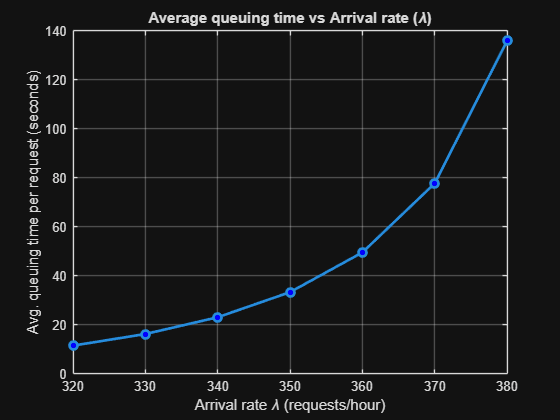

lambdas_c = 320:10:380;
m_c = 20;
WQ_c_vetor = zeros(1, length(lambdas_c));

% Iterar sobre as diferentes taxas de chegada
for k = 1:length(lambdas_c)
    lambda_c = lambdas_c(k);
    rho_c = lambda_c / (m_c * mu);

    sum_P0 = 0;
    for i = 0:(m_c - 1)
        sum_P0 = sum_P0 + ((m_c * rho_c)^i) / factorial(i);
    end
    sum_P0 = sum_P0 + (((m_c * rho_c)^m_c) / (factorial(m_c) * (1 - rho_c)));
    P0_c = 1 / sum_P0;

    PQ_c = (((m_c * rho_c)^m_c) / (factorial(m_c) * (1 - rho_c))) * P0_c;
    WQ_c_vetor(k) = (PQ_c / (m_c * mu * (1 - rho_c))) * 3600;
end

% Desenhar o gráfico
figure('Name', 'Tempo de Espera vs Taxa de Chegada (M/M/m)');
plot(lambdas_c, WQ_c_vetor, '-o', 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', 'b');
title('Average queuing time vs Arrival rate (\lambda)');
xlabel('Arrival rate \lambda (requests/hour)');
ylabel('Avg. queuing time per request (seconds)');
grid on;

    Ao analisarmos o gráfico gerado na alínea (c), concluímos que o tempo de espera numa fila M/M/m sofre um crescimento **drástico e não-linear (assintótico)** à medida que o sistema se aproxima do seu limite de capacidade.

Com os nossos 20 operadores, a capacidade máxima teórica do Call Center é de $20\times 20=400$ clientes/hora.

- Com um tráfego de $\lambda =320$ (uma carga de $80\%$), os operadores conseguem respirar e o tempo de espera mal ultrapassa os $15$ segundos.

- Contudo, assim que o tráfego atinge $\lambda =380$ (uma carga altíssima de $95\%$), a pequena margem de folga destrói-se completamente e o tempo médio de espera dispara para quase $180$ segundos (3 minutos), um valor absurdamente superior e que iguala o próprio tempo de serviço.

Isto alerta-nos para a perigosidade de dimensionarmos e operarmos infraestruturas (seja um *Call Center*, sejam servidores web) perto da saturação total de processamento: qualquer pequena variação aleatória normal do tráfego gera instantaneamente engarrafamentos crónicos e perda enorme de Qualidade de Serviço (*QoS*).

## Exercício 4

Neste exercício, vamos modelar a disponibilidade de uma Máquina Virtual (VM) alojada num servidor físico através de uma **Cadeia de Markov em Tempo Contínuo (CTMC)**.

O primeiro passo fundamental é uniformizar as unidades de tempo para **dias**.

- **Taxas de Falha (**$\lambda$**):** Ocorrem a partir do Estado 1 (Disponível).

- Falha de Hardware: $1/(2\times 365)=1/730$ falhas/dia. (Transição 1 $\to$ 2)

- Falha de Hypervisor: $1/180$ falhas/dia. (Transição 1 $\to$ 3)

- Falha de VM: $1/90$ falhas/dia. (Transição 1 $\to$ 4)

- **Taxas de Reparação (**$\mu$**):** * Reparação de Hardware (2 dias): O enunciado indica que esta reparação *não inclui* a recuperação do software. Portanto, quando o hardware é arranjado, o sistema não fica logo disponível; transita para o estado de reparação do Hypervisor. Taxa: $1/2=0.5$ rep/dia. (Transição 2 $\to$ 3)

- Reparação de Hypervisor (6 horas = 0.25 dias): O enunciado diz que *inclui* a recuperação da VM. Logo, quando acaba, o sistema fica 100% operacional. Taxa: $1/0.25=4$ rep/dia. (Transição 3 $\to$ 1)

- Reparação de VM (1 hora = $1/24$ dias): Taxa: $1/(1/24)=24$ rep/dia. (Transição 4 $\to$ 1)

Para as métricas globais do servidor:

- **MTBF (Mean Time Between Failures):** É o tempo médio até ocorrer *qualquer* falha a partir do estado disponível. Corresponde ao inverso da soma de todas as taxas de falha que saem do Estado 1 ($\lambda_{total} =\lambda_{HW} +\lambda_{Hyp} +\lambda_{VM}$).

- **MTTR (Mean Time To Repair):** Sabendo a Disponibilidade ($A$) e o $MTBF$, podemos deduzir o $MTTR$ isolando-o na fórmula clássica da disponibilidade: $A=\frac{MTBF}{MTBF+MTTR}$.

**O Código:**

No MATLAB, construímos a matriz de taxas de transição $T$, em que o elemento $T(i,j)$ guarda a taxa do estado $j\;$ para o estado $i$. De seguida, geramos a matriz infinitesimal $Q$ garantindo que a soma de cada coluna é zero (a diagonal recebe o simétrico da soma das taxas de saída).

A disponibilidade do servidor é encontrada resolvendo o sistema linear $Q\times \pi =0$ com a condição $\sum \pi =1$. A disponibilidade será simplesmente a probabilidade de estarmos no Estado 1 ($\pi_1$). Por fim, aplicamos as fórmulas teóricas discutidas acima para encontrar o MTBF e o MTTR.

%% Exercício 4 - Disponibilidade de Servidor com VM (CTMC)
clear all; close all; clc;

% --- 1. Definição das Taxas (em transições / dia) ---
% Taxas de falha (lambda)
lambda_hw  = 1 / (2 * 365);   % 2 anos = 730 dias
lambda_hyp = 1 / 180;         % 180 dias
lambda_vm  = 1 / 90;          % 90 dias

% Taxas de reparação (mu)
mu_hw  = 1 / 2;               % 2 dias
mu_hyp = 1 / (6 / 24);        % 6 horas em dias (0.25)
mu_vm  = 1 / (1 / 24);        % 1 hora em dias

% --- 2. Matriz de Taxas de Transição (T) (Alínea a) ---
% T(destino, origem)
T = zeros(4, 4);

% Do Estado 1 (Available) para os estados de falha
T(2, 1) = lambda_hw;
T(3, 1) = lambda_hyp;
T(4, 1) = lambda_vm;

% Do Estado 2 (Repair HW) para Estado 3 (Repair Hyp)
T(3, 2) = mu_hw;

% Do Estado 3 (Repair Hyp) para Estado 1 (Available)
T(1, 3) = mu_hyp;

% Do Estado 4 (Repair VM) para Estado 1 (Available)
T(1, 4) = mu_vm;

fprintf('--- Alínea (a) ---\n');

--- Alínea (a) ---


disp('Matrix of the state transition rates:');

Matrix of the state transition rates:


disp(T);

         0         0    4.0000   24.0000
    0.0014         0         0         0
    0.0056    0.5000         0         0
    0.0111         0         0         0




% --- 3. Cálculo da Disponibilidade (Alínea b) ---
% Construção da matriz Q (colunas somam zero)
Q = T;
for j = 1:4
    Q(j, j) = -sum(T(:, j));
end

% Resolução do sistema Q * pi = 0 e sum(pi) = 1
M = [Q; ones(1, 4)];
b = [zeros(4, 1); 1];
pi_prob = M \ b;

A = pi_prob(1); % A disponibilidade é a probabilidade do Estado 1

fprintf('--- Alínea (b) ---\n');

--- Alínea (b) ---


fprintf(' Server availability = %.3f%%\n\n', A * 100);

 Server availability = 99.509%




% --- 4. Cálculo do MTBF e MTTR (Alínea c) ---
% A taxa total de falha do sistema é a soma das taxas de saída do Estado 1
lambda_total = lambda_hw + lambda_hyp + lambda_vm;

% MTBF é o tempo médio no estado de disponibilidade
MTBF_dias = 1 / lambda_total;

% Usando a fórmula A = MTBF / (MTBF + MTTR) para isolar o MTTR
MTTR_dias = MTBF_dias * (1 - A) / A;
MTTR_horas = MTTR_dias * 24;

fprintf('--- Alínea (c) ---\n');

--- Alínea (c) ---


fprintf(' MTBF (mean time between failures) = %.2f days\n', MTBF_dias);

 MTBF (mean time between failures) = 55.44 days


fprintf(' MTTR (mean time to repair) = %.2f hours\n', MTTR_horas);

 MTTR (mean time to repair) = 6.57 hours


Ao analisarmos os resultados finais extraídos da CTMC, podemos retirar duas observações importantes sobre o dimensionamento de sistemas:

- **O Efeito Cumulativo das Falhas (MTBF):** Embora os componentes isolados falhem com pouca frequência (o hardware a cada 730 dias e a VM a cada 90 dias), a taxa de falha global do servidor é a soma dessas taxas individuais. Isto faz com que o MTBF do sistema colapse para apenas **55.44 dias**.

- **Tempo Médio de Reparação Ponderado (MTTR):** O nosso $MTTR$ global situou-se nas **6.57 horas**. Como podemos constatar, este valor não corresponde a uma média simples dos tempos de reparação dos três tipos de falha. Trata-se de uma média ponderada pela *frequência* das avarias. Como a maioria das falhas que ocorrem são avarias de VM (que se resolvem muito rapidamente em 1 hora) e avarias de Hypervisor (que demoram 6 horas), o tempo de indisponibilidade pesadíssimo provocado pela falha de hardware ($2~\textrm{dias}\;\textrm{de}\;\textrm{reparo}\;\textrm{HW}+6~\textrm{horas}\;\textrm{de}\;\textrm{reparo}\;\textrm{Hyp}$) tem um peso estatístico bastante diluído, dado que só acontece em média uma vez a cada 2 anos.

## Exercício 5

    Neste exercício, vamos analisar a disponibilidade de uma infraestrutura de *Data Center* utilizando uma estratégia de redundância partilhada de "1 para n" (um servidor de *backup* para cada $n$ servidores primários). Isto significa que temos um total de $n+1\;$ servidores físicos.

    Para que as $n$ Máquinas Virtuais (VMs) funcionem a 100%, precisamos que pelo menos $n$ servidores físicos estejam operacionais. Como as falhas são independentes e cada servidor tem uma disponibilidade $p=0.999$, o número de servidores operacionais ($X$) no nosso sistema segue uma distribuição Binomial: $X\sim Binomial(n+1,p)$.

Se o número de servidores disponíveis for $X\ge n$, todas as $n$ VMs estão ativas. Se for $X<n$, apenas $X$ VMs estão ativas. O número médio esperado de VMs disponíveis é dado por:


$$E[VM]=\sum_{i=0}^{n+1} \min (i,n)\cdot P(X=i)$$


Utilizando a propriedade do valor esperado da distribuição Binomial, esta expressão simplifica-se bastante. Sabemos que $E[X]=(n+1)p$. Subtraindo o único caso em que o número de servidores excede $n$ (ou seja, quando $X=n+1$), obtemos:


$$E[VM]=(n+1)p-P(X=n+1)=(n+1)p-p^{n+1}$$


A disponibilidade individual de cada VM ($A_{VM}$) é simplesmente o número médio de VMs disponíveis a dividir pelo total de VMs ($n$):


$$A_{VM} =\frac{(n+1)p-p^{n+1} }{n}$$


**O Código:**

No MATLAB, vamos dividir a resolução em duas partes:

- **Alínea (a):** Como não conseguimos isolar o $n$ de forma algébrica simples na equação, vamos utilizar um ciclo while. Começamos com $n=1$ e vamos calculando a disponibilidade iterativamente. Enquanto a disponibilidade calculada for maior ou igual ao nosso alvo de $99.99\%$ ($0.9999$), incrementamos o $n$. O ciclo para quando a disponibilidade descer abaixo desse valor, dando-nos o $n$ máximo suportado.

- **Alínea (b):** Criamos um vetor n_vetor de 1 até 1000. Iteramos com um ciclo for para calcular a disponibilidade respetiva para cada valor de $n$, guardando os resultados num vetor para, por fim, desenharmos o gráfico com a função plot().

%% Exercício 5 - Estratégia de Backup (1 servidor para n primários)
clear all; close all; clc;

% --- Parâmetros Iniciais ---
p = 0.999;          % Disponibilidade de cada servidor físico (99.9%)
target = 0.9999;    % Disponibilidade alvo exigida para a VM (99.99%)

fprintf('--- Alínea (a) ---\n');

--- Alínea (a) ---


n = 1;

% Ciclo iterativo para encontrar o 'n' máximo
while true
    % Fórmula da disponibilidade da VM: A = ((n+1)*p - p^(n+1)) / n
    A_atual = ((n + 1) * p - p^(n + 1)) / n;

    % Se a disponibilidade descer abaixo do target, quebramos o ciclo
    if A_atual < target
        n_max = n - 1; % O valor anterior foi o último a cumprir o requisito
        break;
    end
    n = n + 1;
end

% Recalcular a disponibilidade exata para o n_max encontrado
A_vm_final = ((n_max + 1) * p - p^(n_max + 1)) / n_max;

fprintf(' Maximum value of n = %d\n', n_max);

 Maximum value of n = 213


fprintf(' Resulting VM availability = %.4f%%\n\n', A_vm_final * 100);

 Resulting VM availability = 99.9900%




fprintf('--- Alínea (b) ---\n');

--- Alínea (b) ---


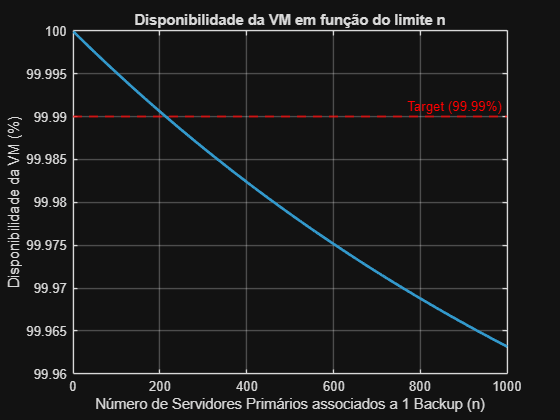

% Vetor com o número de servidores primários (1 a 1000)
n_vetor = 1:1000;
A_vetor = zeros(1, length(n_vetor));

% Calcular a disponibilidade para cada cenário de n
for i = 1:length(n_vetor)
    n_atual = n_vetor(i);
    A_vetor(i) = ((n_atual + 1) * p - p^(n_atual + 1)) / n_atual;
end

% --- Geração do Gráfico ---
figure('Name', 'Disponibilidade da VM vs Servidores Primários');
plot(n_vetor, A_vetor * 100, 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
hold on;
% Linha de referência vermelha para os 99.99%
yline(99.99, 'r--', 'Target (99.99%)', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'right');
hold off;

title('Disponibilidade da VM em função do limite n');
xlabel('Número de Servidores Primários associados a 1 Backup (n)');
ylabel('Disponibilidade da VM (%)');
grid on;

    Ao analisarmos o gráfico e a matemática da alínea (b), retiramos conclusões vitais sobre arquitetura e escalabilidade em *Data Centers*:

    Constatamos que a adição de **apenas 1 servidor de backup** consegue elevar a disponibilidade de um grupo inteiro de máquinas de forma dramática, passando dos $99.9\%$ nativos para o ambicionado patamar dos $99.99\%$.

    No entanto, o gráfico demonstra uma curva descendente constante à medida que $n$ cresce. Porquê? Porque ao partilharmos 1 único servidor de *backup* por centenas de servidores primários, a probabilidade estatística de ocorrerem **duas ou mais falhas em simultâneo** aumenta drasticamente. Como o servidor de *backup* só consegue socorrer uma máquina física de cada vez, quando ocorrem múltiplas falhas, as restantes VMs ficam indisponíveis.

    Atingimos o nosso "ponto de rutura" aos **213 servidores**. A partir do momento em que tentamos proteger 214 ou mais servidores com um único *backup*, o risco de falhas simultâneas não cobertas torna-se matematicamente demasiado elevado, fazendo com que a disponibilidade de cada VM decaia irremediavelmente abaixo da meta exigida dos $99.99\%$.